load('Time_Doppler_matrix.mat');
mat1=Time_Doppler_matrix;
load('Time_Doppler_matrix_1_Hz.mat')
mat2=Time_Doppler_matrix;
load('Time_Doppler_matrix_005s.mat')
mat3=Time_Doppler_matrix;
clear Time_Doppler_matrix

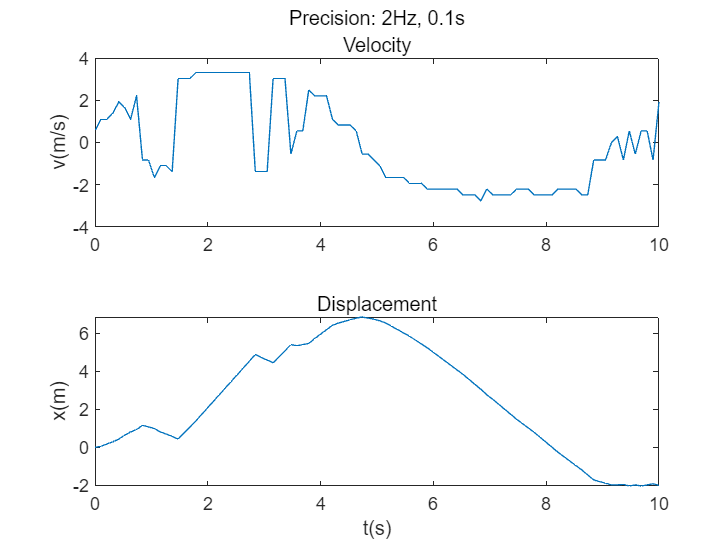

drawMovement(mat1,'Precision: 2Hz, 0.1s','2Hz_0.1s.png')

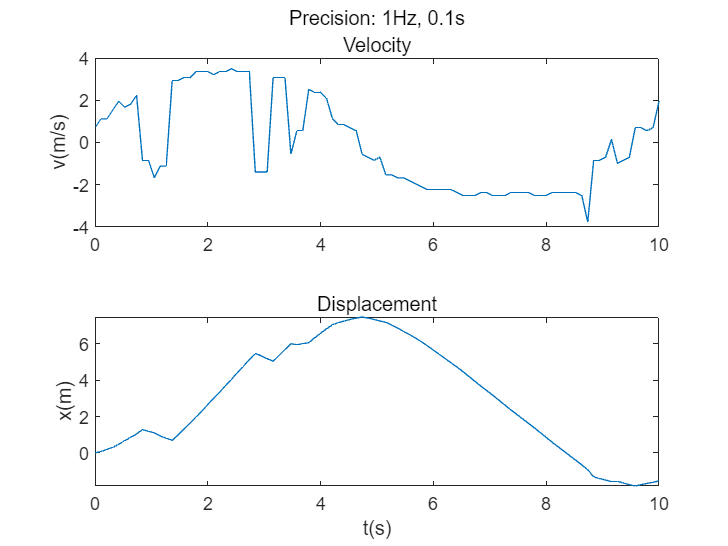

drawMovement(mat2,'Precision: 1Hz, 0.1s','1Hz_0.1s.png')

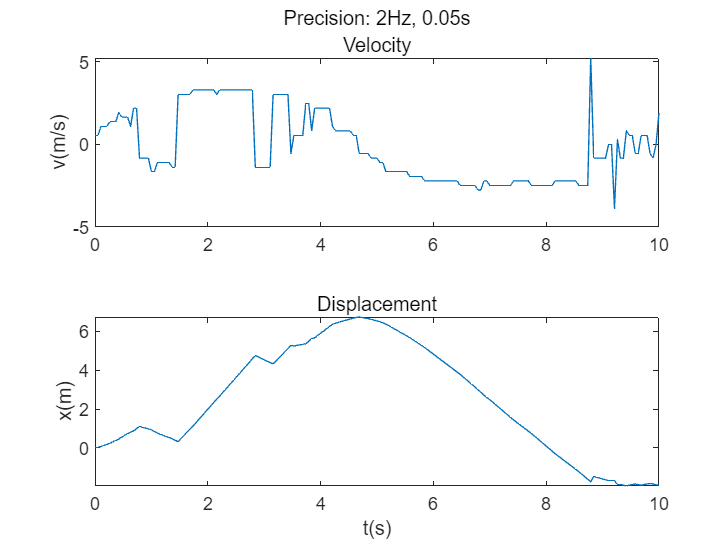

drawMovement(mat3,'Precision: 2Hz, 0.05s','2Hz_0.05s.png')

function drawMovement(Mat,Title,varargin)
    Nt=length(Mat);
    Nf=length(Mat(1,:));

    speed=zeros(1,length(Mat));
    for k=1:length(Mat)
        [~,speed(k)]=max(Mat(k,:));
        %现在speed是索引
    end
    
    %t=(1:length(speed))./(length(Mat)/9.5);
    t=linspace(0,10,Nt);

    %speed=(speed-21).*2;%索引是1:41，修正为-20:2:20
    speed=(speed-(Nf+1)/2);
    %索引由1:N变为-N/2:N/2
    speed=speed.*(80/Nf);
    speed=speed.*(3e8/2123e6);


$$v=\frac{f_D \cdot c}{f_C },\;f_C =2123\textrm{e6}$$


    h=figure;subplot(2,1,1),plot(t,speed),subtitle('Velocity'),ylabel('v(m/s)'),title(Title)
    loc=zeros(1,length(Mat));
    for k=2:length(Mat)
        loc(k)=loc(k-1)+speed(k-1)*(t(2)-t(1));%t(2)-t(1)是数据点间的时间间隔
    end

    subplot(2,1,2),plot(t,loc),subtitle('Displacement'),ylabel('x(m)'),xlabel('t(s)')

    if isempty(varargin)
        return
    else
        saveas(h,varargin{1},'png')
    end
end